close all
clear

## Initialising main variables

## 

 years, , and 

 . 

k12 = 0.58;
k21 = 1.87;
M = 280;
m1_initial = 87.5;
m2_initial = M - m1_initial;

## **Functions for dmdt**

Two functions called` lowerOcean` and `upperOcean` which take the same arguments `(k12, k21, m1, m2) `and return the derivatives  and  respectively. 

function dm1dt = lowerOcean(k12, k21, m1, m2)
    dm1dt = -k12 * m1 + k21 * m2;
end

function dm2dt = upperOcean(k12, k21, m1, m2)
    dm2dt = k12 * m1 - k21 * m2;
end

## First Calculation

Solving for  over a time interval of 0 to 5 years in steps of 3 months, using Euler's method. Storing the output data in variables m1_e3 and m2_e3. Calculating the concentrations of phosphorous in the lower and upper ocean at years & assigning these to variables m1pe and m2pe respectively.

t_e3 = 0 : 0.25 : 5;

% Solve for m1 and m2 over a time interval of 0 to 5 years in steps of 3 months
[m1_e3, m2_e3] = eulersMethod(k12, k21, m1_initial, m2_initial, 0, 0.25, 5);

% Calculate concentrations of phosphorus in the lower and upper ocean at 5 years
m1pe = m1_e3(end);
m2pe = m2_e3(end);

## Repeating with different h values

Solving for  over a time interval of 0 to 5 years in steps of 1 month, using Euler's method. Storing the output data in variables m1_e1 and m2_e1.

t_e1 = 0 : 1/12 : 5;

[m1_e1, m2_e1] = eulersMethod(k12, k21, m1_initial, m2_initial, 0, 1/12, 5);


## Comparing the two results

Plotting these estimates in Figure 1 as follows:

- Plot m1_e3 and m2_e3 using a blue line with + markers for each point.

- Plot m1_e1 and m2_e1 using a green line with "." markers (a dot) for each point.  Using markersize 8 so we can see the points

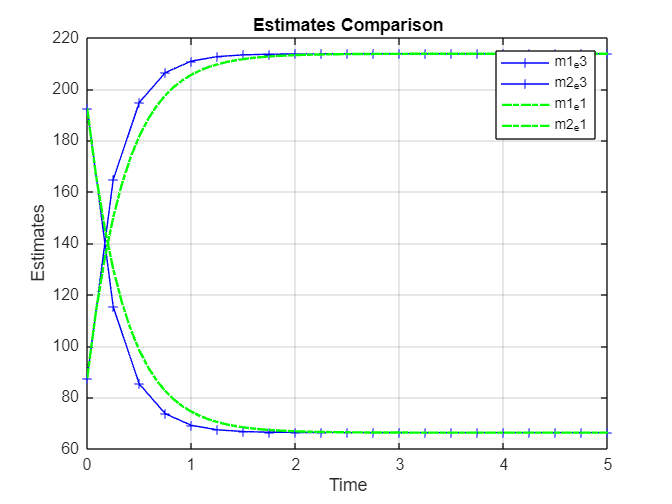

% Render estimates in Figure 1
figure;
plot(t_e3, m1_e3, 'b-+');
hold on;
plot(t_e3, m2_e3, 'b-+');
plot(t_e1, m1_e1, 'g-.', 'LineWidth', 1.5, 'MarkerSize', 8);
plot(t_e1, m2_e1, 'g-.', 'LineWidth', 1.5, 'MarkerSize', 8);
xlabel('Time');

ylabel('Estimates');
title('Estimates Comparison');
legend('m1_e3', 'm2_e3', 'm1_e1', 'm2_e1');
grid on;
hold off;


## Future Analysis

Assume, the ocean temperature changes by 1 deg Celcius. This causes  to increase by 5 % . Repeat above stuff but store the output in variables m1_e1_hot and m2_e1_hot. 

Plotting these new estimates in Figure 2 as follows:

- Plot m1_e1 and m2_e1 using a black line with x markers for each point.  

- Plot m1_e1_hot and m2_e1_hot using a red line with "." markers for each point and markersize of 8

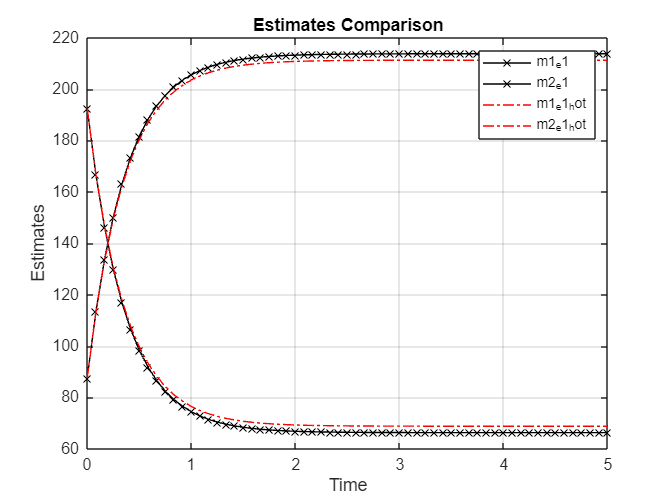

% The ocean temperature changes by 1 deg Celsius
k12 = k12 * 1.05;

% Calculate new estimates after the temperature change

[m1_e1_hot, m2_e1_hot] = eulersMethod(k12, k21, m1_initial, m2_initial, 0, 1/12, 5);

% Render new estimates in Figure 2
figure;
plot(t_e1, m1_e1, 'k-x');
hold on;
plot(t_e1, m2_e1, 'k-x');
plot(t_e1, m1_e1_hot, 'r-.', 'MarkerSize', 8);
plot(t_e1, m2_e1_hot, 'r-.', 'MarkerSize', 8);
xlabel('Time');
ylabel('Estimates');
title('Estimates Comparison');
legend('m1_e1', 'm2_e1', 'm1_e1_hot', 'm2_e1_hot');
grid on;
hold off;

## Comparing the future with the present

Using the results from Task 6,  h = 1 month, calculating the percentage change in phosphorous in the lower and upper ocean after 3 years.

Assigning these values to the variable m1_change_hot and m2_change_hot. 

Using the following calculation to measure percentage change: , where is the value of m after the change and *m* is the value before the change.

Appling these to changes in both .

Three_years = find(t_e1 == 3);

% Calculate the percentage change in phosphorus in the lower and upper ocean after 3 years
m1_change_hot = ((m1_e1_hot(Three_years) - m1_e1(Three_years)) / m1_e1(Three_years)) * 100;
m2_change_hot = ((m2_e1_hot(Three_years) - m2_e1(Three_years)) / m2_e1(Three_years)) * 100;

## Euler's Algorithm

function [m1, m2] = eulersMethod(k12, k21, m1_0, m2_0, t0, h, tf)

    % Euler's method for solving ODEs

    t = t0 : h : tf;
    
    m1(1) = m1_0;
    m2(1) = m2_0;

    % Euler's method iteration
    
    for i = 1:length(t)-1
        m1(i+1) = m1(i) + h * lowerOcean(k12, k21, m1(i), m2(i));
        m2(i+1) = m2(i) + h * upperOcean(k12, k21, m1(i), m2(i));
    end

end